Interface01NEuler

Teste da função NEuler com exemplo da sebenta de AM2

Arménio Correia | armenioc@isec.pt

aula04T | 05/03/2024

clear
syms y(t)

%help function_handle
strF = "y+exp(3*t)"

strF = "y+exp(3*t)"

f =@(t,y) eval(vectorize(strF))

f = function_handle with value:
    @(t,y)eval(vectorize(strF))


%f(0,1)
a = 1

a = 1

b = 1.5

b = 1.5000

n = 2

n = 2

y0 = 2

y0 = 2


sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

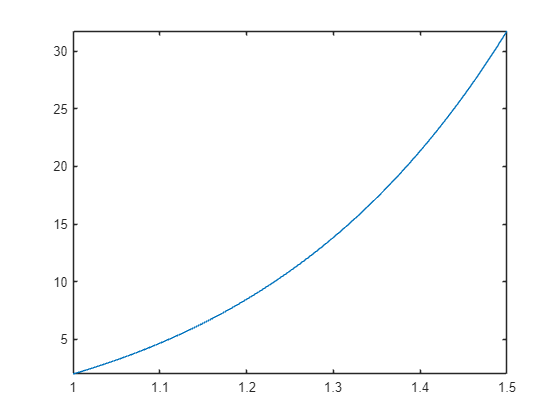

fplot(sExata,[a,b])

g =@(t) eval(vectorize(char(sExata)))

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))



[t,yEuler] = NEuler(f,a,b,n,y0);
yExata = g(t);
erroEuler = abs(yExata-yEuler);
A = [t.',yExata.',yEuler.',erroEuler.'];
tabelaResultados = array2table(A,"VariableNames", ...
                   {'t','Exata','Euler','erroEuler'})

tabelaResultados = 3×4 table
     t      Exata     Euler     erroEuler
    ____    ______    ______    _________

       1         2         2          0  
    1.25    10.933    7.5214      3.412  
     1.5    31.748    20.032     11.716  


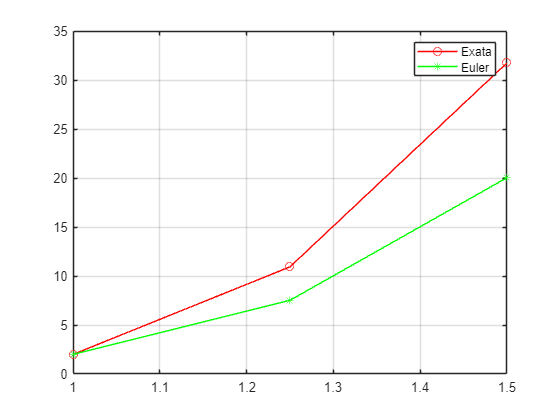


plot(t,yExata,"-ro")
hold on
plot(t,yEuler,"-g*")
hold off
grid on
legend('Exata','Euler')